# Chapter 1, Section 2 (Part 2)

In this activity, we will investigate systems of equations that have no solutions. Such systems are called **inconsistent**. Let's start with an example.

# Example #1

Solve the following system for $x$, $y$, and $z$.


$$\begin{array}{rcl}
x+y+z&=&1\\
x-y-2z&=&2\\
2x-z&=&1
\end{array}$$


**Solution:** Let's manipulate the system a bit to make clear the augmented matrix for the system.


$$\begin{array}{rcl}
1x+1y+1z&=&1\\
1x-1y-2z&=&2\\
2x+0y-1z&=&1
\end{array}$$


We write our augmented matrix and highlight the leading entry in the first row.


$$\pmatrix{[1] & 1 & 1 & 1\cr1 & -1 & -2 & 2\cr2 & 0 & -1 & 1}$$


Now we use elementary row operations to zero out the entries in the column below our highlighted leading entry in row one.

- Replace row two with the sum of itself and -1 times row one.

- Replace row three with the sum of itself and -2 times row one.


$$\pmatrix{[1] & 1 & 1 & 1\cr1 & -1 & -2 & 2\cr2 & 0 & -1 & 1}\ \matrix{~\cr R_2-R_1\cr R_3-2R_1}\qquad\longrightarrow\qquad \pmatrix{[1] & 1 & 1 & 1\cr 0 & -2 & -3 & 1\cr 0 & -2 & -3 & -1}$$


Let's check our work with Matlab. First, enter the augmented matrix. 

A=[1 1 1 1;1 -1 -2 2;2 0 -1 1]

A =      1     1     1     1
     1    -1    -2     2
     2     0    -1     1


This matches our hand-calculated augmented matrix. Now, we'll save the rows of matrix A in the variables r1, r2, and r3. The notation A(1,:) selects row one, every column, of matrix A.

r1=A(1,:)

r1 =      1     1     1     1


The notation A(2,:) selects row two, every column, of matrix A.

r2=A(2,:)

r2 =      1    -1    -2     2


The notation A(3,:) selects row three, every column, of matrix A.

r3=A(3,:)

r3 =      2     0    -1     1


Now, we'll perform our elementary row operations using Matlab. Recall that we replaced row two with $R_2-R_1$ and row three with $R_3-2R_1$ but row one remained the same. Let's create a new matrix A with these results.

A=[r1;r2-r1;r3-2*r1]

A =      1     1     1     1
     0    -2    -3     1
     0    -2    -3    -1


This matches our hand-calculations above, so we are correct thus far, so let's restore each new row in r1, r2, and r3. 

r1=A(1,:)

r1 =      1     1     1     1


r2=A(2,:)

r2 =      0    -2    -3     1


r3=A(3,:)

r3 =      0    -2    -3    -1


Now, let's highlight the leading entry in row two.


$$\pmatrix{1 & 1 & 1 & 1\cr 0 & [-2] & -3 & 1\cr 0 & -2 & -3 & -1}$$


Now we will use an elementary row operation to zero out the entries in the column below the highlighted entry in row two. Replace row three with the sum of itself and -1 times row two.


$$\pmatrix{1 & 1 & 1 & 1\cr 0 & [-2] & -3 & 1\cr 0 & -2 & -3 & -1}\ \matrix{~\cr ~\cr R_3-R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 1 & 1\cr 0 & [-2] & -3 & 1\cr 0 & 0 & 0 &-2}$$


We can check this step with Matlab. Row one and row two remain the same, but row three is replaced with $R_3-R_2$.

A=[r1;r2;r3-r2]

A =      1     1     1     1
     0    -2    -3     1
     0     0     0    -2


Now we can write the system represented by this row echelon form.


$$\begin{array}{rcl}
x+y+z&=&1\\
-2y-3z&=&1\\
0x+0y+0z&=&-2
\end{array}$$


Note that no values of $x$, $y$, and $z$ will satisfy the last equation $0x+0y+0z=-2$, so this system does not have a solution. This is called an **inconsistent** system of equations.

**Visualizing the Solution:** Let's sketch the three planes so that we can see why our system has no solutions. Recall our system of equations.


$$\begin{array}{rcl}
x+y+z&=&1\\
x-y-2z&=&2\\
2x-z&=&1
\end{array}$$


Let's solve each equation for $z$. 


$$\begin{array}{rcl}
z&=&1-x-y\\
z&=&\frac{x}{2}-\frac{y}{2}+1\\
z&=&2x-1
\end{array}$$


Our system does not have a solution, so we'll just guess a region over which to plot the graphs of our equations. If our choice does not work well, then we will adjust our choice until we get an image that we really like. Let's start with choosing twenty $x$-values between -5 and 5 and twenty $y$-values between -5 and 5. 

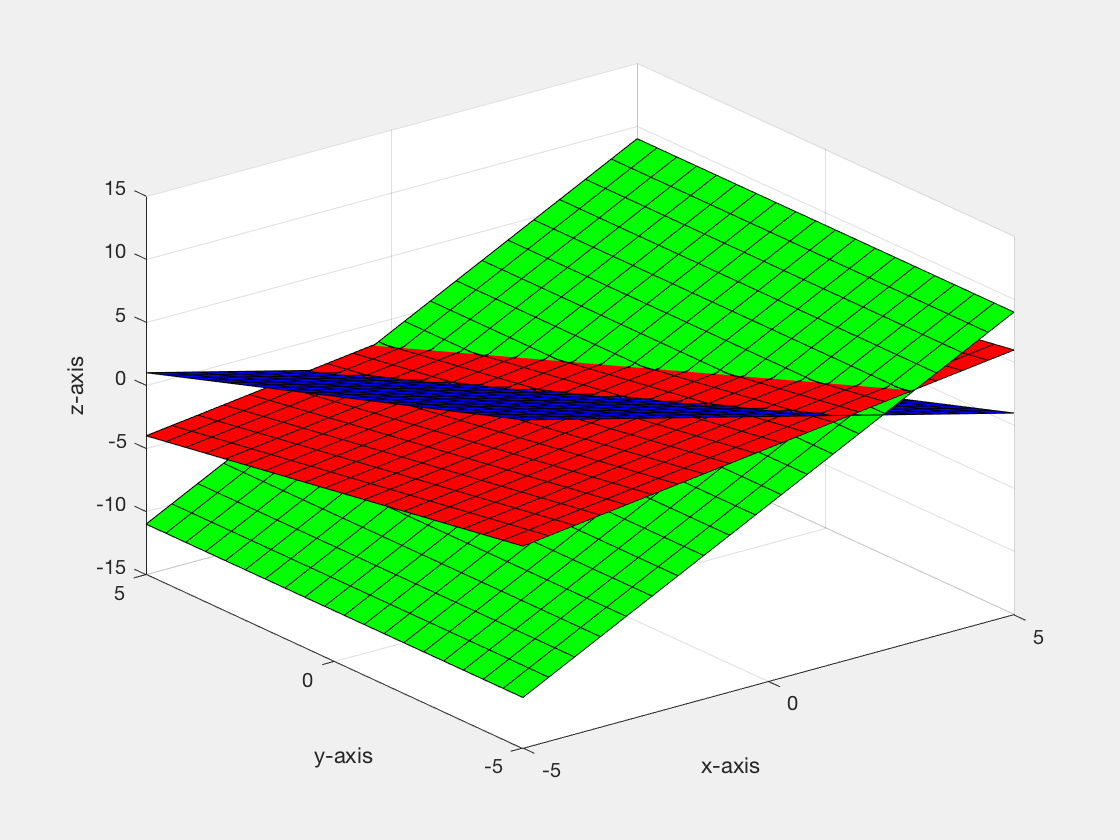

[X,Y]=meshgrid(linspace(-5,5,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

Note that the green and red planes seem to intersect in a line that is parallel to the blue plane, showing that there are no points that lie on all three planes. However, looking at the x-axis, it seems that the area we would really like to estimate lies between 0 and 5. Let's try that interval for $x$ and $y$.

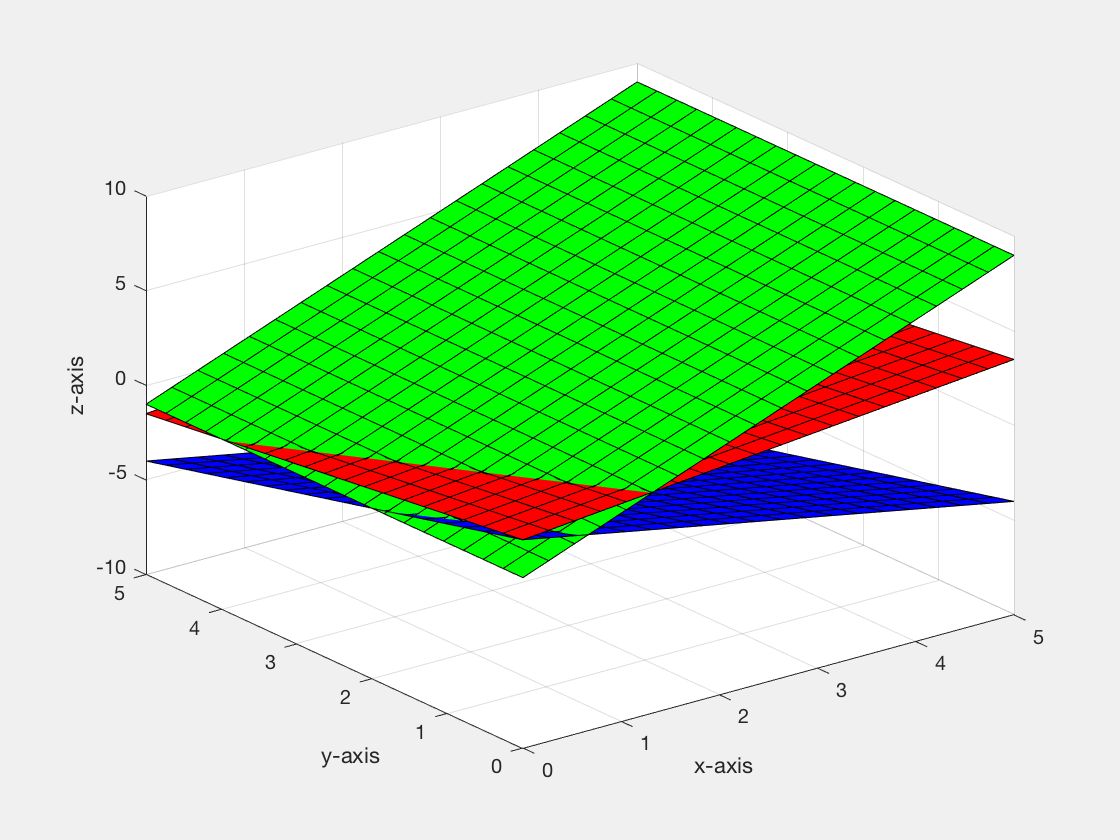

[X,Y]=meshgrid(linspace(0,5,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

Looking at the x-axis, it seems that the area we would really like to estimate lies between -1 and 2. Let's try that interval for $x$ and $y$.

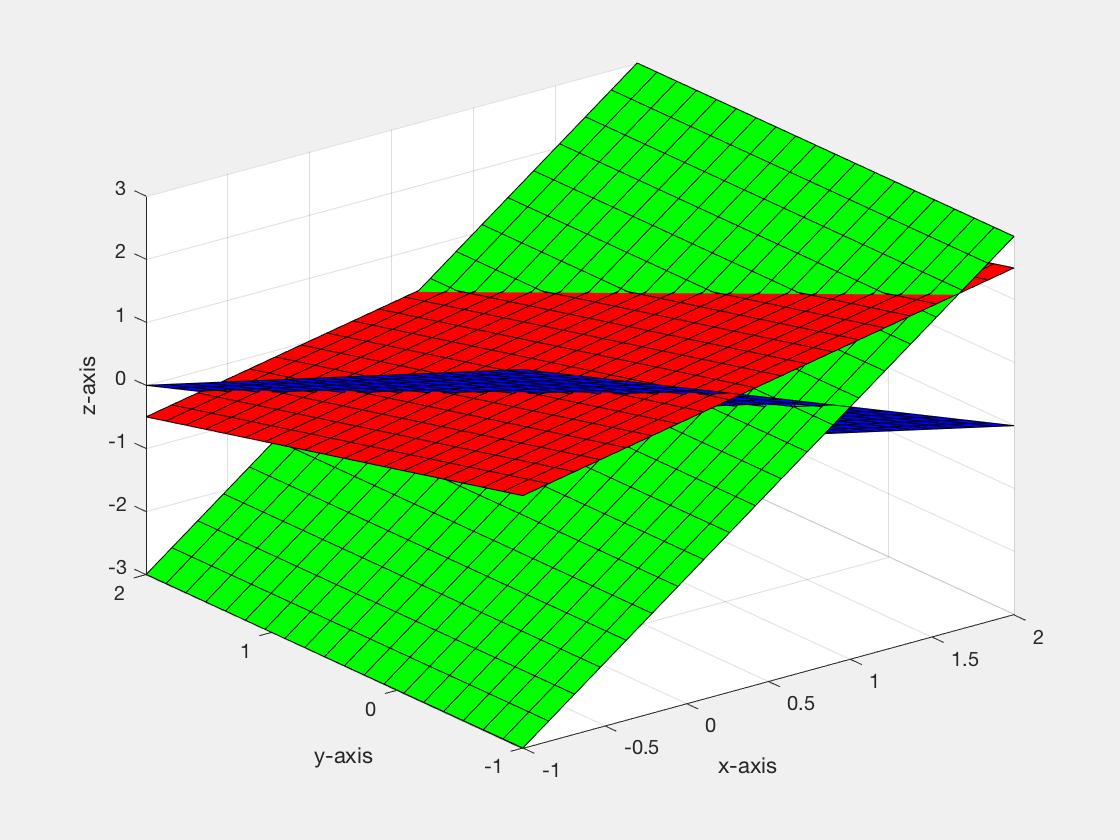

[X,Y]=meshgrid(linspace(-1,2,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off

Now, let's turn the rotate3d command on, so we can rotate our image.

[X,Y]=meshgrid(linspace(-1,2,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off
rotate3d on

As you rotate the image with your mouse, you will see in the lower left corner of the figure window two numbers Az and El. The azimuth, A`z`, is the horizontal rotation about the *z*-axis as measured in degrees from the negative *y*-axis. Positive values indicate counterclockwise rotation of the viewpoint. E`l` is the vertical elevation of the viewpoint in degrees. Positive values of elevation correspond to moving above the object; negative values correspond to moving below the object. After rotating the image for a while, I picked this view.

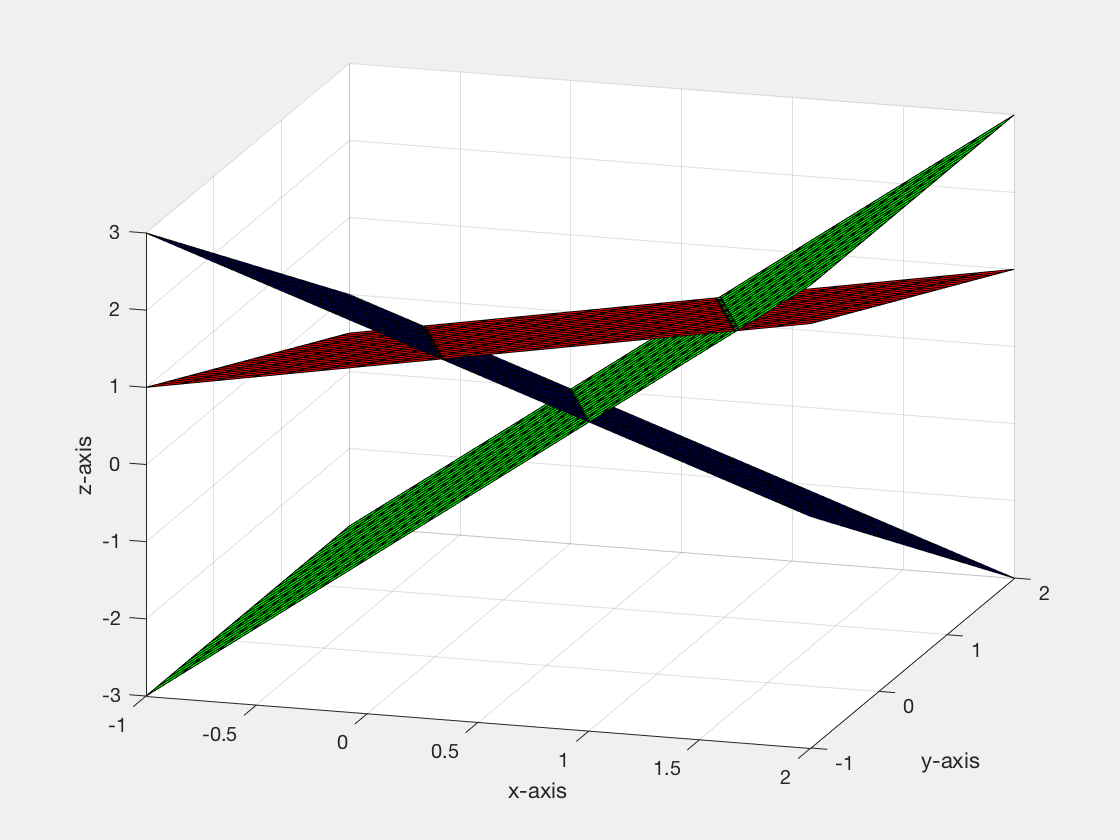

[X,Y]=meshgrid(linspace(-1,2,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off
view(17,21)

We can really see that there are no points that lie on all three planes. Here is another view.

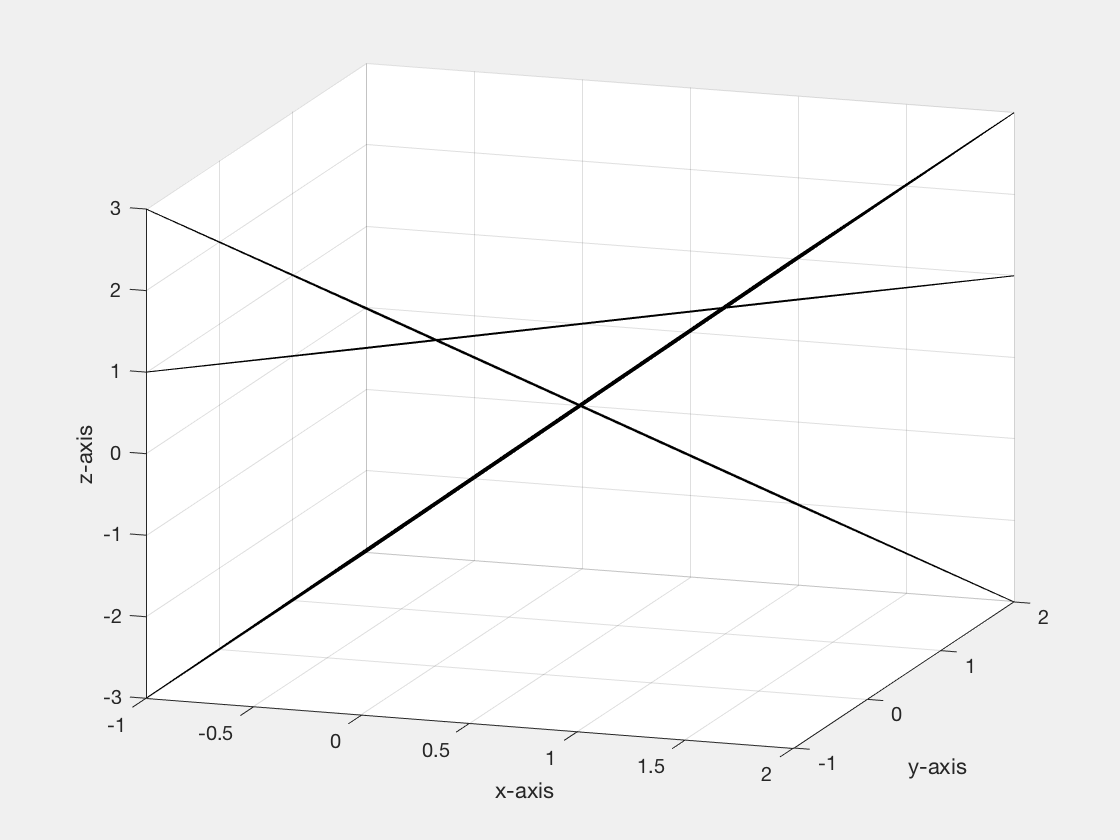

[X,Y]=meshgrid(linspace(-1,2,20));
Z=1-X-Y;
surf(X,Y,Z,'FaceColor','blue')
hold on
Z=X/2-Y/2+1;
surf(X,Y,Z,'FaceColor','red')
Z=2*X-1;
surf(X,Y,Z,'FaceColor','green')
grid on
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
hold off
view(18.8,17.5)